load data_stat;

anom = zeros(size(C_1));

for i = 1:numel(anom)
    anom(i) = C_1{i}{3};
end

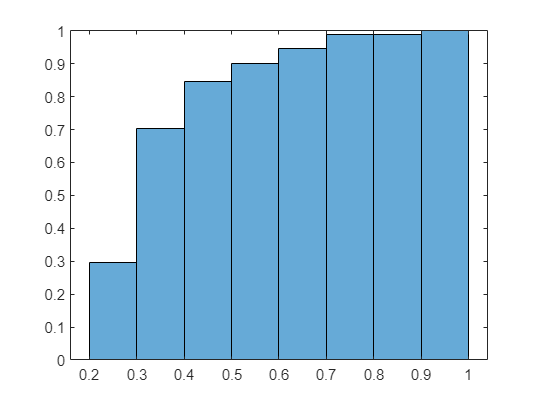

h = histogram(anom);
h.Normalization = "cdf"; % функция распределения вероятности, вероятность опреденного значения. в 70% случаях я буду получать значения НЕ БОЛЬШЕ чем 0.4

%% Оценка параметров гауссовой смеси
gm = fitgmdist(anom',2);

% Проверка гипотезы о гауссовой смеси
[h,p] = kstest(anom,'CDF',gm); % тест Колмогорова-Смирнова

Error using kstest
Hypothesized CDF matrix must have 2 columns.

if h == 1
    disp('Данные не соответствуют гауссовой смеси распределений')
else
    disp('Данные соответствуют гауссовой смеси распределений')
end
